## TALLER — LÓGICA DIFUSA 

#### Asignatura : Inteligencia Computacional Aplicada

#### Docente    : Cesar Andrey Perdomo Charry


clear; clc; close all;
rng(42);


**PASO 1. SISTEMA MAMDANI «PROPINA» POR CÓDIGO**

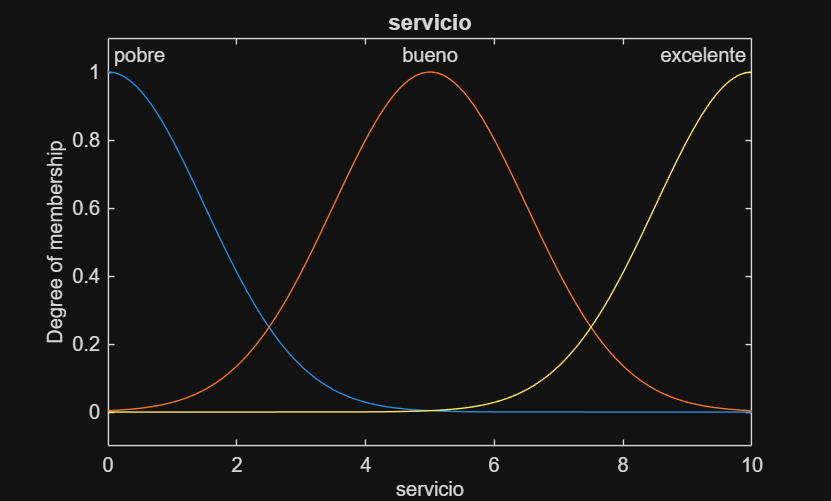

fis = mamfis("Name","propina");
fis = addInput(fis,[0 10],"Name","servicio");
fis = addMF(fis,"servicio","gaussmf",[1.5 0], "Name","pobre");
fis = addMF(fis,"servicio","gaussmf",[1.5 5], "Name","bueno");
fis = addMF(fis,"servicio","gaussmf",[1.5 10],"Name","excelente");
fis = addInput(fis,[0 10],"Name","comida");
fis = addMF(fis,"comida","trapmf",[-2 0 1 3], "Name","rancia");
fis = addMF(fis,"comida","trapmf",[7 9 10 12],"Name","deliciosa");
fis = addOutput(fis,[0 30],"Name","propina");
fis = addMF(fis,"propina","trimf",[0 5 10],  "Name","baja");
fis = addMF(fis,"propina","trimf",[10 15 20],"Name","media");
fis = addMF(fis,"propina","trimf",[20 25 30],"Name","generosa");
reglas = [ ...
    "servicio==pobre | comida==rancia => propina=baja"; ...
    "servicio==bueno => propina=media"; ...
    "servicio==excelente | comida==deliciosa => propina=generosa"];
fis = addRule(fis,reglas);

figure; plotmf(fis,"input",1); title("servicio");

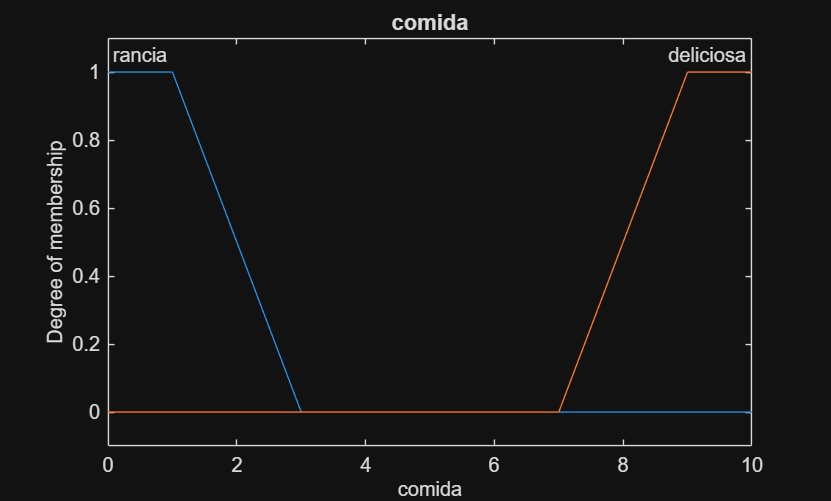

figure; plotmf(fis,"input",2); title("comida");

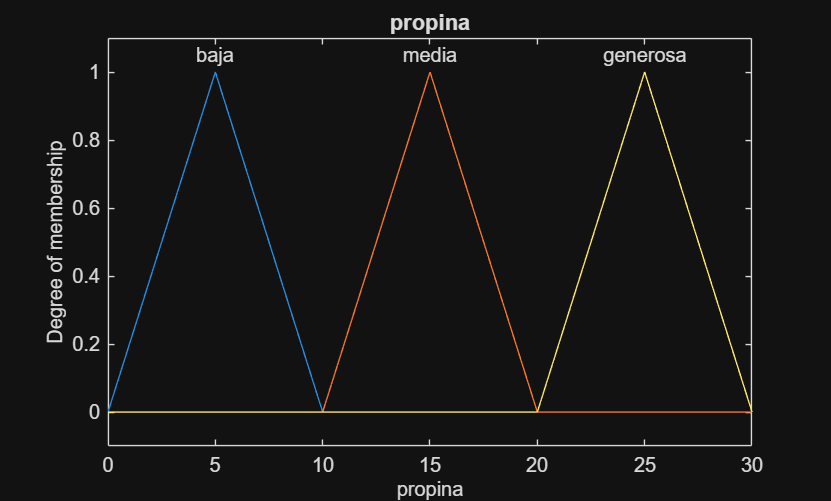

figure; plotmf(fis,"output",1); title("propina");

**PASO 2. EVALUAR Y COMPARAR CON LA REFERENCIA**

salida = evalfis(fis,[1 2]);
fprintf("Propina (centroide) para servicio=1, comida=2: %.4f %%\n", salida);

Propina (centroide) para servicio=1, comida=2: 5.5586 %


verificar("Coincide con la referencia de MathWorks y del cuaderno de Colab (5.5586)", abs(salida - 5.5586) < 0.01, "revise parámetros de las funciones de pertenencia");

[OK]      Coincide con la referencia de MathWorks y del cuaderno de Colab (5.5586)


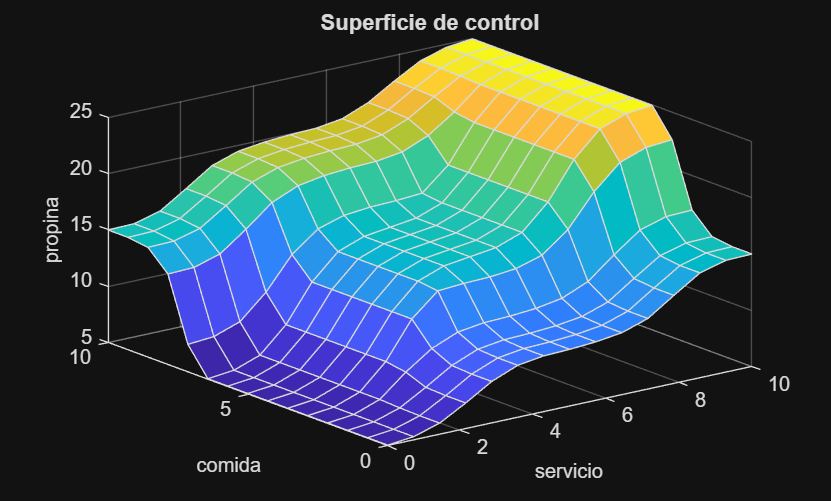

figure; gensurf(fis); title("Superficie de control");

**PASO 3. LA MISMA IDEA CON LA APP FUZZY LOGIC DESIGNER**

%  1) fuzzyLogicDesigner(fis)  abre el sistema en la app.
%  2) En la pestaña Rules y Surface/Rule Viewer cambie entradas y vea la salida.
%  3) Para construirlo desde cero: fuzzyLogicDesigner  -> New FIS -> Mamdani.
%  4) Export -> To Workspace guarda un objeto FIS que se evalúa con evalfis.
fuzzyLogicDesigner(fis)


**PASO 4. SUGENO DE ORDEN CERO**

fisS = sugfis("Name","propinaSugeno");
fisS = addInput(fisS,[0 10],"Name","servicio");
fisS = addMF(fisS,"servicio","gaussmf",[1.5 0], "Name","pobre");
fisS = addMF(fisS,"servicio","gaussmf",[1.5 5], "Name","bueno");
fisS = addMF(fisS,"servicio","gaussmf",[1.5 10],"Name","excelente");
fisS = addInput(fisS,[0 10],"Name","comida");
fisS = addMF(fisS,"comida","trapmf",[-2 0 1 3], "Name","rancia");
fisS = addMF(fisS,"comida","trapmf",[7 9 10 12],"Name","deliciosa");
fisS = addOutput(fisS,[0 30],"Name","propina");
fisS = addMF(fisS,"propina","constant",5, "Name","baja");
fisS = addMF(fisS,"propina","constant",15,"Name","media");
fisS = addMF(fisS,"propina","constant",25,"Name","generosa");
fisS = addRule(fisS,reglas);
salidaS = evalfis(fisS,[1 2]);
fprintf("Propina Sugeno: %.4f %%  (en el cuaderno de Colab: 5.3445)\n", salidaS);

Propina Sugeno: 5.3075 %  (en el cuaderno de Colab: 5.3445)


verificar("Sugeno entre las constantes 5 y 25", salidaS >= 5 && salidaS <= 25, "");

[OK]      Sugeno entre las constantes 5 y 25


**PASO 5. CLASIFICADOR DIFUSO CON REGLAS EXTRAÍDAS DE DATOS (IRIS)**

[x,t] = iris_dataset;                       % x: 4 x 150, t: 3 x 150 (one-hot)
X = x';  y = vec2ind(t)';                   % observaciones en filas; clase 1..3
cv = cvpartition(y,"HoldOut",0.3);
Xtr = X(training(cv),:); ytr = y(training(cv));
Xte = X(test(cv),:);     yte = y(test(cv));

% 5a. Reglas extraídas de los datos (equivalente al cuaderno de Python)
mins = min(Xtr); maxs = max(Xtr);           % solo con entrenamiento
XtrN = wm_normalizar(Xtr,mins,maxs); XteN = wm_normalizar(Xte,mins,maxs);
NMF = 3;
[R,clasesR,gradosR] = wm_extraer(XtrN,ytr,NMF);
pred = wm_predecir(XteN,R,clasesR,NMF);
accWM = mean(pred == yte);
fprintf("Reglas extraídas (3 etiquetas): %d | exactitud en prueba: %.3f\n", size(R,1), accWM);

Reglas extraídas (3 etiquetas): 15 | exactitud en prueba: 0.911


verificar("Hay menos reglas que muestras de entrenamiento", size(R,1) < size(Xtr,1), "");

[OK]      Hay menos reglas que muestras de entrenamiento


verificar("Exactitud en prueba > 80 %", accWM > 0.80, "revise la normalización con mins/maxs de entrenamiento");

[OK]      Exactitud en prueba > 80 %



% 5b. genfis con agrupamiento sustractivo (estima las salidas con los datos)
%     Se recortan los datos de prueba al rango de entrenamiento para evitar el aviso «Input expects a value in range».
XteC = min(max(Xte, mins), maxs);
fisSub = genfis(Xtr,ytr,genfisOptions("SubtractiveClustering","ClusterInfluenceRange",0.5));
pSub = evalfis(fisSub,XteC);
pSub(isnan(pSub)) = 1;                      % sin regla activa
pSub = min(max(round(pSub),1),3);
fprintf("SubtractiveClustering: %d reglas | exactitud en prueba: %.3f\n", numel(fisSub.Rules), mean(pSub == yte));

SubtractiveClustering: 4 reglas | exactitud en prueba: 1.000



% 5c. genfis con rejilla: solo se cuenta la estructura
%     OJO: GridPartition crea la ESTRUCTURA (n^4 reglas) y no entrena las salidas; si se evalúa sin ajustar
%     (con tunefis o anfis) predice casi una constante y la exactitud cae a ~0.333. No lo use para medir exactitud.
opcGrid = genfisOptions("GridPartition");
opcGrid.NumMembershipFunctions = 3;
opcGrid.InputMembershipFunctionType = "trimf";
fisGrid = genfis(Xtr,ytr,opcGrid);
fprintf("GridPartition (3 MF por entrada): %d reglas (solo estructura)\n", numel(fisGrid.Rules));

GridPartition (3 MF por entrada): 81 reglas (solo estructura)


verificar("La rejilla produce 3^4 = 81 reglas", numel(fisGrid.Rules) == 81, "genfis con GridPartition crea una regla por combinación");

[OK]      La rejilla produce 3^4 = 81 reglas


%  Para ver las reglas en la app: fuzzyLogicDesigner(fisSub)


**PASO 6. FUZZY C-MEANS**

Xn = normalize(X,"range");                  % escala cada columna a [0,1]
[centros,U] = fcm(Xn,3);                    % U es 3 x 150; cada columna suma 1

Iteration count = 1, obj. fcn = 17.7245
Iteration count = 2, obj. fcn = 13.7094
Iteration count = 3, obj. fcn = 13.6615
Iteration count = 4, obj. fcn = 13.2836
Iteration count = 5, obj. fcn = 10.9073
Iteration count = 6, obj. fcn = 6.53922
Iteration count = 7, obj. fcn = 5.7924
Iteration count = 8, obj. fcn = 5.4139
Iteration count = 9, obj. fcn = 5.26285
Iteration count = 10, obj. fcn = 5.23662
Iteration count = 11, obj. fcn = 5.23344
Iteration count = 12, obj. fcn = 5.23309
Iteration count = 13, obj. fcn = 5.23305
Iteration count = 14, obj. fcn = 5.23304
Minimum improvement reached.


[~,grupo] = max(U,[],1);
verificar("Los grados de cada punto suman 1", all(abs(sum(U,1)-1) < 1e-6), "");

[OK]      Los grados de cada punto suman 1


% Pureza: fracción de puntos cuyo grupo coincide con la clase mayoritaria de ese grupo
pureza = 0;
for k = 1:3
    pureza = pureza + max(histcounts(y(grupo(:) == k),1:4));
end
pureza = pureza/numel(y);
fprintf("Pureza de FCM sobre Iris: %.3f (el cuaderno de Colab mide ARI = 0.729)\n", pureza);

Pureza de FCM sobre Iris: 0.893 (el cuaderno de Colab mide ARI = 0.729)


**PASO 7. EXPERIMENTO: NÚMERO DE FUNCIONES DE PERTENENCIA VS REGLAS Y EXACTITUD**

for n = 2:5
    [Rn,cn,~] = wm_extraer(XtrN,ytr,n);
    pn = wm_predecir(XteN,Rn,cn,n);
    linea = sprintf("n_mf = %d | reglas = %3d | exactitud difusa = %.3f", n, size(Rn,1), mean(pn == yte));
    try   % árbol con el mismo número de hojas (requiere Statistics and Machine Learning Toolbox)
        arbol = fitctree(Xtr,ytr,"MaxNumSplits",max(1,size(Rn,1)-1));
        linea = [linea sprintf(" | árbol = %.3f", mean(predict(arbol,Xte) == yte))];
    catch
        linea = [linea ' | árbol: no disponible'];
    end
    disp(linea);
end

    "n_mf = 2 | reglas =   7 | exactitud difusa = 0.733"    " | árbol = 0.956"

    "n_mf = 3 | reglas =  15 | exactitud difusa = 0.911"    " | árbol = 0.956"

    "n_mf = 4 | reglas =  26 | exactitud difusa = 0.867"    " | árbol = 0.956"

    "n_mf = 5 | reglas =  42 | exactitud difusa = 0.933"    " | árbol = 0.956"



Nota: 

- Las reglas se extraen de los datos (solo las combinaciones que aparecen), como en el cuaderno de Python.

- La rejilla completa de genfis tendría n^4 reglas (16, 81, 256 y 625). Como la partición es otra, las cifras no son idénticas a las del cuaderno de Python.

- Ajuste de parámetros: tunefis (recomendado). anfis está desaconsejado en versiones recientes; consulte la documentación de su versión.

%% =========================================================================
%  FUNCIONES LOCALES
% =========================================================================
function verificar(nombre, ok, pista)
    if ok
        fprintf("[OK]      %s\n", nombre);
    else
        fprintf("[REVISAR] %s  ->  %s\n", nombre, pista);
    end
end

function Xn = wm_normalizar(X, mins, maxs)
    % Normaliza a [0,1] con los mínimos y máximos de ENTRENAMIENTO
    Xn = (X - mins) ./ (maxs - mins + 1e-12);
    Xn = min(max(Xn,0),1);
end

function G = wm_grados(Xn, nmf)
    % Grados de pertenencia N x F x nmf con nmf triángulos uniformes en [0,1]
    centros = linspace(0,1,nmf);
    ancho = centros(2) - centros(1);
    G = zeros(size(Xn,1), size(Xn,2), nmf);
    for k = 1:nmf
        G(:,:,k) = max(0, 1 - abs(Xn - centros(k))/ancho);
    end
end

function [R, clases, grados] = wm_extraer(Xn, y, nmf)
    % Wang-Mendel simplificado: una regla por muestra; si hay antecedentes repetidos se conserva el de mayor grado
    G = wm_grados(Xn, nmf);
    [gmax, dom] = max(G, [], 3);          % etiqueta dominante por característica
    grado = prod(gmax, 2);
    [R, ~, ic] = unique(dom, "rows");
    clases = zeros(size(R,1),1);
    grados = zeros(size(R,1),1);
    for i = 1:size(Xn,1)
        k = ic(i);
        if grado(i) > grados(k)
            grados(k) = grado(i);
            clases(k) = y(i);
        end
    end
end

function pred = wm_predecir(Xn, R, clases, nmf)
    % Clasifica con la regla más fuerte (t-norma = producto)
    G = wm_grados(Xn, nmf);
    fuerza = ones(size(Xn,1), size(R,1));
    for f = 1:size(R,2)
        for k = 1:size(R,1)
            fuerza(:,k) = fuerza(:,k) .* G(:, f, R(k,f));
        end
    end
    [m, idx] = max(fuerza, [], 2);
    pred = clases(idx);
    pred(m == 0) = 1;
end